# Optimizing MR and NR

This Live Script helps you visualize performance as you optimize for different register blocking parameters ($m_R$ and $n_R$).

To gather the performance data, in the command (terminal) window change the directory to Assignments/Week2/C/.  After implementing a new implementation, execute it with "make" to gather data.  You will want to activate the plotting of a new performance curve by changing "( 0 )" to "( 1 )" in the appropriate place.

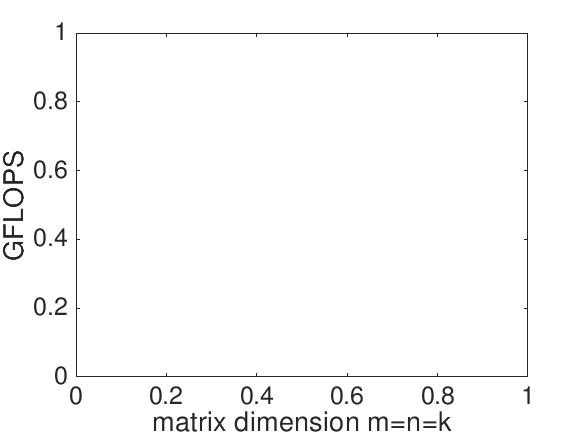

plot_colors = [ 0 0 0; 0 0 1; 0 1 0; 0 1 1; 1 0 0; 1 0 1; 1 1 0; 1 1 1];

% Create figure
figure1 = figure('Name','GFLOPS');

% Create axes, labels, legends.  In future routines for plotting performance, 
% the next few lines will be hidden in the script.
axes2 = axes('Parent',figure1);
hold(axes2,'on');
ylabel( 'GFLOPS', 'FontName', 'Helvetica Neue' );
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );
box(axes2,'on');
set( axes2, 'FontName', 'Helvetica Neue', 'FontSize', 18);


system( 'cp ../../../Week1/C/data/output_IJP.m .' );

cp: cannot stat '../../../Week1/C/data/output_IJP.m': No such file or directory


output_IJP   % load data for IJP ordering

'output_IJP' is not found in the current folder or on the MATLAB path, but exists in:
    /MATLAB Drive/LAFF-On-PfHP/Assignments/Week2/C/data

Change the MATLAB current folder or add its folder to the MATLAB path.

assert( max(abs(data(:,6))) < 1.0e-10, ...
    'Hmmm, better check if there is an accuracy problem');
plot( data(:,1), data(:,5), 'DisplayName', 'IJP', 'MarkerSize', 8, 'LineWidth', 2, ...
    'Marker', '.', 'LineStyle', '-.', 'Color', plot_colors( 2,: ) );
  
% Plot performance data for JPI
if ( 1 )
  output_JPI   % load data for JPI ordering
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JPI', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', '.', 'LineStyle', '-.', 'Color', plot_colors( 3,: ) );
end

% Plot time data for JI_4x1Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_4x1Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_4x1Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '-', 'Color', plot_colors( 1,: ) );
end

% Plot time data for JI_4x2Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_4x2Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_4x2Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '-', 'Color', plot_colors( 2,: ) );
end

% Plot time data for JI_4x4Kernel (to plot change "0" to "1")
if ( 1 ) 
  output_JI_4x4Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_4x4Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 3,: ) );
end

% Plot time data for JI_4x8Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_4x8Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_4x8Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '-', 'Color', plot_colors( 4,: ) );
end

% Plot time data for JI_4x12Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_4x12Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_4x12Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '-', 'Color', plot_colors( 5,: ) );
end

% Plot time data for JI_4x14Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_4x14Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_4x14Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '-', 'Color', plot_colors( 6,: ) );
end

% Plot time data for JI_8x1Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_8x1Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_8x1Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'x', 'LineStyle', '-', 'Color', plot_colors( 2,: ) );
end

% Plot time data for JI_8x2Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_8x2Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_8x2Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'x', 'LineStyle', '-', 'Color', plot_colors( 3,: ) );
end

% Plot time data for JI_8x4Kernel  (to plot change "0" to "1")
if ( 1 ) 
  output_JI_8x4Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_8x4Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'x', 'LineStyle', '-', 'Color', plot_colors( 1,: ) );
end

% Plot time data for JI_8x6Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_8x6Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_8x6Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'x', 'LineStyle', '-', 'Color', plot_colors( 4,: ) );
end

% Plot time data for JI_8x8Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_8x8Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_8x8Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'x', 'LineStyle', '-', 'Color', plot_colors( 5,: ) );
end

% Plot time data for JI_12x1Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_12x1Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_12x1Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', '*', 'LineStyle', '-', 'Color', plot_colors( 2,: ) );
end

% Plot time data for JI_12x2Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_12x2Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_12x2Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', '*', 'LineStyle', '-', 'Color', plot_colors( 3,: ) );
end

% Plot time data for JI_12x4Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_12x4Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_12x4Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', '*', 'LineStyle', '-', 'Color', plot_colors( 1,: ) );
end

% Plot time data for JI_12x6Kernel  (to plot change "0" to "1")
if ( 0 ) 
  output_JI_12x6Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'JI\_12x6Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', '*', 'LineStyle', '-', 'Color', plot_colors( 4,: ) );
end
% Optionally show the reference implementation performance data
if ( 1 )
  plot( data(:,1), data(:,3), 'MarkerSize', 8, 'LineWidth', 1, ...
        'LineStyle', '-', 'DisplayName', 'Ref', 'Color', plot_colors( 1,: ) );
end

% Adjust the x-axis and y-axis range to start at 0
v = axis;                   % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )   % start the x axis and y axis at zero

% Optionally change the top of the graph to capture the theoretical peak
if ( 0 )
    turbo_clock_rate = 4.3;
    flops_per_cycle = 16;
    peak_gflops = turbo_clock_rate * flops_per_cycle;

    axis( [ 0 v(2) 0 peak_gflops ] )  
end

legend2 = legend( axes2, 'show' );
set( legend2, 'Location', 'northeast', 'FontSize', 18) ;

% Uncomment if you want to create a pdf for the graph
print( 'Plot_optimize_MRxNR.png', '-dpng' );